## I) Load and understand the data

load('Raw_data_10_frames.mat')


## II) From Raw ultrasound data to high quality images of the brain 

### DAS beamforming template:

% Define the reconstruction grid (in SI units) :
% 1) define pixel size
BfStruct.dx = 0.1e-3/2 ; % pixel size in x dimension. A good start is (lambda)/2
BfStruct.dz = 0.1e-3/2; % pixel size in y dimension. A good start is (lambda)/2

% 2) definition of the field of view limits
BfStruct.z0 = 0.00;                  % depth coordinate of the first (most shallow) beamformed point (m)
BfStruct.z1 = 9.0e-3;                   % depth coordinate of the last (deepest) beamformed point (m)
BfStruct.x0 = -6e-3;                    % lateral coordinate of the first beamformed point (m)
BfStruct.x1 =  6e-3;                    % lateral coordinate of the last beamformed point (m)


x_vect = BfStruct.x0:BfStruct.dx:BfStruct.x1; % full reconstruction vector in x direction
z_vect = BfStruct.z0:BfStruct.dz:BfStruct.z1; % full reconstruction vector in z direction

% Position of the transducer piezo electric elements
xTransducer = AcqParameters.xTransducer;
zTransducer = 0*xTransducer;

fs    = AcqParameters.RxFreq ; % sampling frequency short name to simplify code reading
AcqParameters.fNum       = 1; % "fNumber". Sets a condition to take into account transducer directivity

ImgOut = zeros(length(z_vect), length(x_vect), 10);
for frame = 10

    for angle_i = 1:length(AcqParameters.Angles)
        % Loop to sum coherently all the different emitted angles. This is called "coherent
        % compounding" (see the lecture slides). It will virtually
        % focus the emitted waves on the pixel we are reconstructing, to enhance the
        % signals. In short, it consist in summing the different emissions with correct delays to make them
        % interfere constructively on the pixel location.
        for iX = 1:length(x_vect)
            for iZ = 1:length(z_vect)
                % 2 loops on the pixels to reconstruct an image point by
                % point
                x_m = x_vect(iX);
                z_m = z_vect(iZ);
                focal_law_forward = (z_m * cos(AcqParameters.Angles(angle_i))...
                    + x_m * sin(AcqParameters.Angles(angle_i)) + ...
                    AcqParameters.TxCenter * (abs(sin(AcqParameters.Angles(angle_i)))))/AcqParameters.c...
                    + AcqParameters.pulse_delay + AcqParameters.NbHcycle / 4 / AcqParameters.TxFreq ; % in [s]
                focal_law_forward = focal_law_forward*fs;% in [samples]
                focal_law_return =  sqrt((x_m - xTransducer).^2 + (z_m-zTransducer).^2 )./AcqParameters.c ; % in [s]
                focal_law_return = focal_law_return*fs; % in [samples]
                focal_law  = focal_law_forward + focal_law_return -  AcqParameters.skipSample;

                % loop on the transducer elements : the signals received on
                % all the transducer elements are summed with the correct
                % delay for each pixel.
                for transducer = 1:AcqParameters.nbPiezos
                    if  (abs(x_m-AcqParameters.xTransducer(transducer)) <= z_m/AcqParameters.fNum/2)
                        if focal_law(transducer)<size(rf_data,1)
                            dist2floor = focal_law(transducer) - floor(focal_law(transducer));
                            ImgOut( iZ, iX, frame) = ImgOut(iZ, iX,  frame) + (1-dist2floor)*double(rf_data(floor(focal_law(transducer)),transducer, angle_i, frame))+ dist2floor*double(rf_data(floor(focal_law(transducer))+1,transducer, angle_i, frame));

                        end
                    end
                end
            end
        end
    end

end


#### Display 1 frame of your data with the proper dimensions

Be sure to display one of the frames you reconstructed

## Find the skull induced aberration law

#### 1) Locate a bubble on the image. 

You can open a figure externally (not in the live script right column), and use the ginput function. Don't hesitate to zoom on the bubble beforehands, to be precise. Try to find a bubble that is: reasonably well resolved, so that you can pinpoint it easily, and located around the center in the x dimension, and as deep as possible. This ensures that the wavefront backscattered by the bubble will reach all the transducer elements.

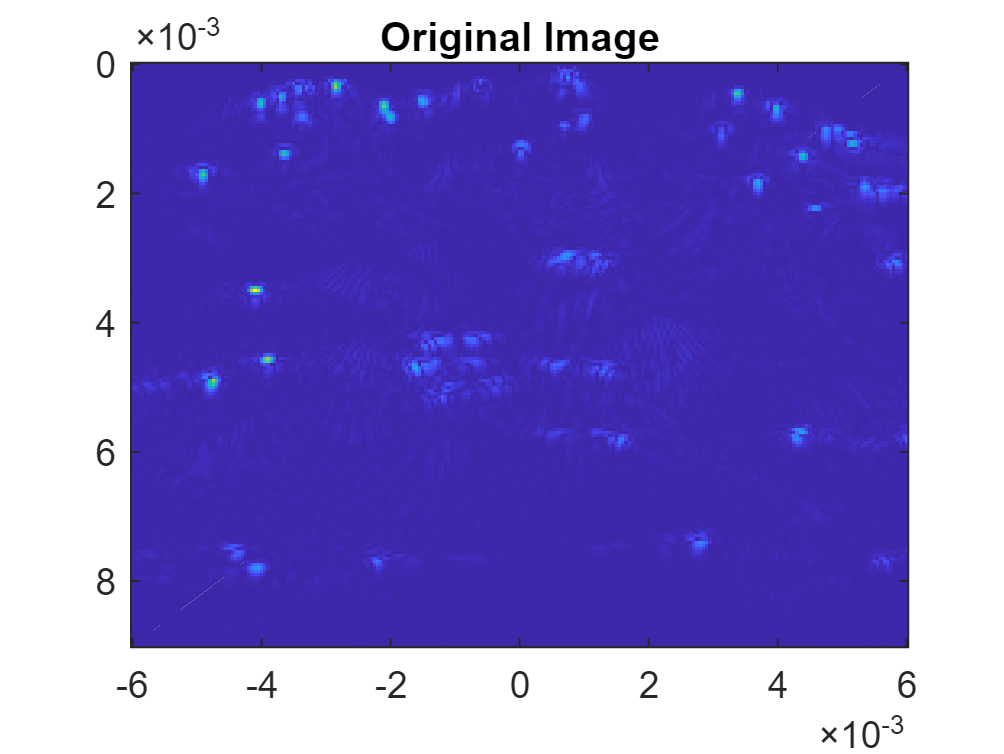

fh = figure();

#### 2) Using the geometrical delay corresponding to this bubble position, extract the flattened wavefront from the raw rf signals. Display this wavefront

The geometrical delay is the same that in the beamformer, the only thing that changes is that we don't need to loop on x_m and z_m anymore, we just have to compute the focal law for x_m = x_0 and z_m = z_0

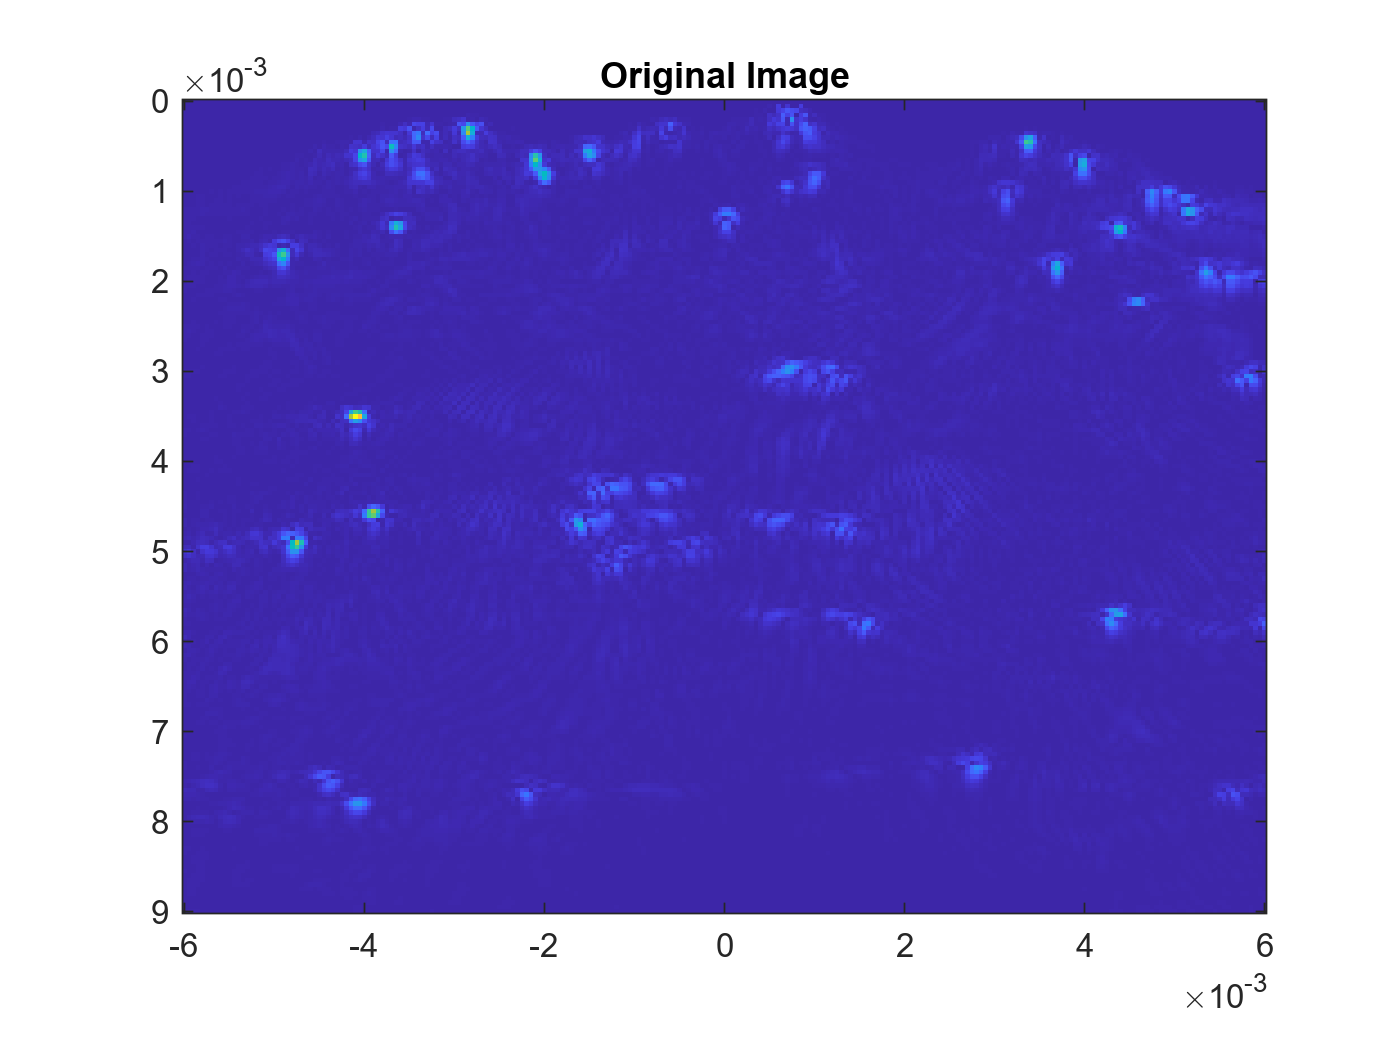

Error using ginput
Interrupted by figure deletion


n_samples = 25; % number of time samples to extract the entire wavefront of interest
rf_interest = zeros( AcqParameters.nbAngles, n_samples*2 + 1, AcqParameters.nbPiezos);


focal_law_forward = zeros(AcqParameters.nbAngles, AcqParameters.nbPiezos);
focal_law_return = zeros(AcqParameters.nbAngles, AcqParameters.nbPiezos);
focal_law = zeros(AcqParameters.nbAngles, AcqParameters.nbPiezos);


for angle_i = 1:length(AcqParameters.Angles) 
    % loop on all the different emitted angles. This is useful enhance the
    % signals coming from the bubble with respect to everything else. In
    % short, it consist in summing the different emissions to make them
    % interfere constructively on the bubble location.

    focal_law_forward = (z_0 * cos(AcqParameters.Angles(angle_i))...
        + x_0 * sin(AcqParameters.Angles(angle_i)) + ...
        AcqParameters.TxCenter * (abs(sin(AcqParameters.Angles(angle_i)))))/AcqParameters.c...
        + AcqParameters.pulse_delay + AcqParameters.NbHcycle / 4 / AcqParameters.TxFreq ; %
    focal_law_forward = focal_law_forward*fs;% [samples]
    focal_law_return = sqrt((x_0 - xTransducer).^2 + (z_0- zTransducer).^2 )./AcqParameters.c ;
    focal_law_return = focal_law_return*fs ; % [samples]
    focal_law = focal_law_forward + focal_law_return -  AcqParameters.skipSample;

    for transducer = 1:AcqParameters.nbPiezos
        rf_piezo = double(rf_data(:, transducer, angle_i, frame));
        rf_interest(angle_i,:, transducer) = rf_piezo(...
            floor(focal_law( transducer))-n_samples:floor(focal_law(transducer))+n_samples);
    end
end

rf_uncurved_bubble = squeeze(sum(rf_interest, 1)); % 
figure, imagesc(rf_uncurved_bubble)


#### 3) Interpolate this data to have a higher temporal resolution. Display the interpolated wavefront

This step is optional, you can use the interp1 function, and interpolate 10 times. 

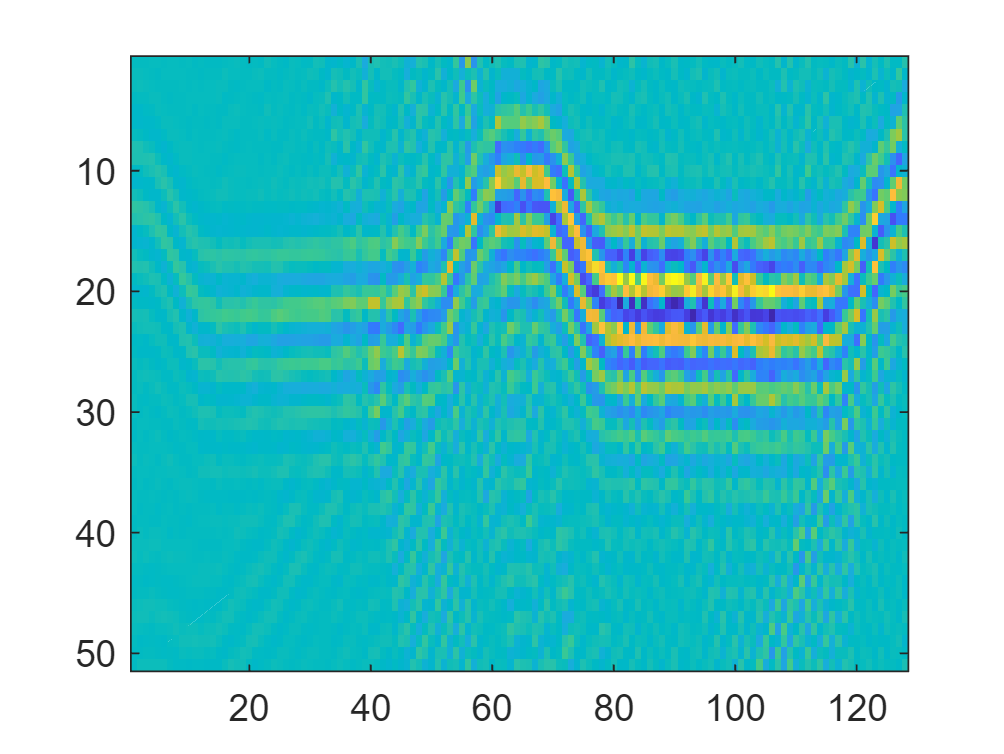

N_interp = 10;
finterp =fs*N_interp;

rf_interp = zeros( N_interp*n_samples*2+1 , AcqParameters.nbPiezos);

for transducer = 1:AcqParameters.nbPiezos
    rf_interp(:, transducer) = ; % fill this gap
end
figure, imagesc(rf_interp)


#### 3) Find the relative delays between the transducer elements. 

Visually you can see the wavefront is received at a different time point for each transducer. You can find this time point with many different methods. The simplest is to look for the position of the maximum for each transducer (matlab function max, check the help). 

If this doesn't work, a more robust method is to use a cross-correlation (Matlab function xcorr, check the help) between a reference signal (for instance a clear signal picked up by a transducer), and all the other signals. This will give you the correlation coefficient for different lags applied to the 2 signals, and the maximum of correlation corresponds to a lag where the signals are aligned.

Tips: 1) Remember to put the delay in seconds. 

2) this delay should be relatively smooth, if you see a few spikes, try to smooth it (smooth function, or manually), to have the best correction possible.

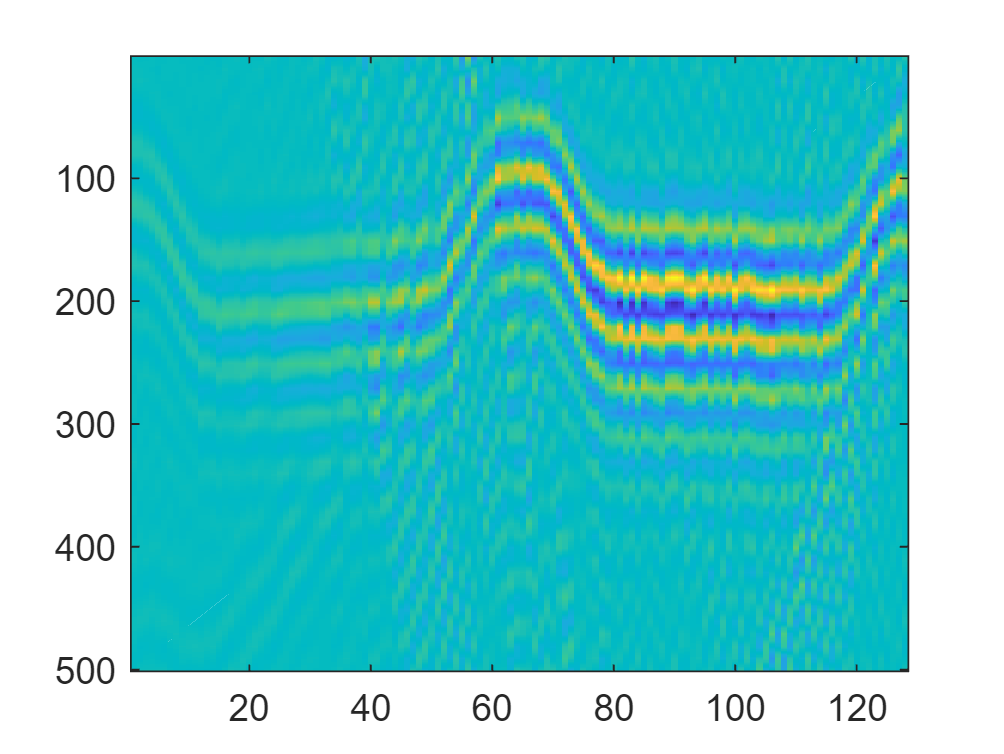



% if finding the max position doesn't work and you want to use a cross-correlation,
% the reference signal can be a mean over a few transducers, as follows:
sig_ref = mean(rf_interp(:,80:110),2);

## Reconstruct a high quality image by correcting the DAS beamformer:

#### Adaptive beamformer code:

Add the aberration delay you just calculated in the return focal law of the original beamformer.  

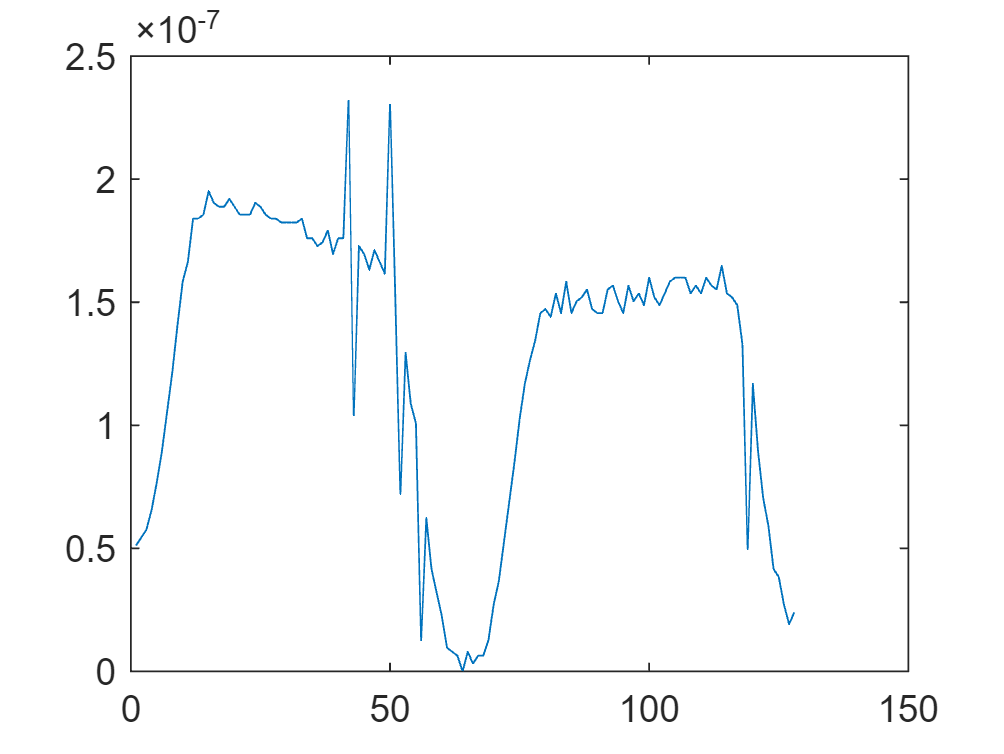

% Define the reconstruction grid (in SI units) :
% 1) define pixel size
BfStruct.dx = 0.1e-3/2 ; % pixel size in x dimension. A good start is (lambda)/2
BfStruct.dz = 0.1e-3/2; % pixel size in y dimension. A good start is (lambda)/2


% 2) definition of the field of view limits
BfStruct.z0 = 0.00;                  % depth coordinate of the first (most shallow) beamformed point (m)
BfStruct.z1 = 9.0e-3;                   % depth coordinate of the last (deepest) beamformed point (m)
BfStruct.x0 = -6e-3;                    % lateral coordinate of the first beamformed point (m)
BfStruct.x1 =  6e-3;                    % lateral coordinate of the last beamformed point (m)


x_vect = BfStruct.x0:BfStruct.dx:BfStruct.x1; % full reconstruction vector in x direction
z_vect = BfStruct.z0:BfStruct.dz:BfStruct.z1; % full reconstruction vector in z direction

% Position of the transducer piezo electric elements
xTransducer = AcqParameters.xTransducer;
zTransducer = 0*xTransducer;

fs    = AcqParameters.RxFreq ; % sampling frequency short name to simplify code reading
AcqParameters.fNum       = 1; % "fNumber". Sets a condition to take into account transducer directivity

ImgOut_Corr = zeros(length(z_vect), length(x_vect), 10);
for frame = 10

    for angle_i = 1:length(AcqParameters.Angles) % loop on the emitted angles
        % 2 loops on the pixels
        for iX = 1:length(x_vect) 
            for iZ = 1:length(z_vect)
                x_m = x_vect(iX);
                z_m = z_vect(iZ);
                focal_law_forward = (z_m * cos(AcqParameters.Angles(angle_i))...
                    + x_m * sin(AcqParameters.Angles(angle_i)) + ...
                    AcqParameters.TxCenter * (abs(sin(AcqParameters.Angles(angle_i)))))/AcqParameters.c...
                    + AcqParameters.pulse_delay + AcqParameters.NbHcycle / 4 / AcqParameters.TxFreq ; % in [s]
                focal_law_forward = focal_law_forward*fs;% in [samples]
                focal_law_return =  ; % in [s]
                focal_law_return = focal_law_return*fs ; % in [samples]
                focal_law  = focal_law_forward + focal_law_return -  AcqParameters.skipSample;
                
                % loop on the transducer elements
                for transducer = 1:AcqParameters.nbPiezos
                    if  (abs(x_m-AcqParameters.xTransducer(transducer)) <= z_m/AcqParameters.fNum/2)
                        if focal_law(transducer)<size(rf_data,1)
                            dist2floor = focal_law(transducer) - floor(focal_law(transducer));
                            ImgOut_Corr( iZ, iX, frame) = ImgOut_Corr(iZ, iX,  frame) + (1-dist2floor)*double(rf_data(floor(focal_law(transducer)),transducer, angle_i, frame))+ dist2floor*double(rf_data(floor(focal_law(transducer))+1,transducer, angle_i, frame));
                           
                        end
                    end
                end
            end
        end
    end

end


## Display the corrected image and comment

What do you think of the image quality, better or worse ? How can you quantify it? (bubble replicas, spreading, in different parts of the image, etc...)

## III. Bubble Localization

#### This 2nd part of the project is completely independant from the 1st. 

The objective here is to locate the bubbles in the images. To do so, we will use several characteristics of bubbles:

1) they are very bright

2) they appear on the images as the PSF of the system

3) they flow along with the blood in the vasculature, so a bubble should appear in a few consecutive frames at slightly different positions.

### Load data - 1 block, and display it

*Display the temporal mean of IQF to visualize blood vessels. This representation is what is called the Power Doppler (PD) image. *

load('C:\Users\Labo-Justine\Downloads\Cropped_images\Cropped_images\BF_IQ_cropped_bloc001.mat')


### *1) Take 1 frame of IQF, and find all local intensity maxima. Display it to compare it to the PD image. Does it look like it worked?*

*Tips: Matlab function imregionalmax*

### *2) From the data you have, try to find the PSF of the imaging system, and display it.*

*Tips: How do the bubbles appear on the image ? The PSF is relatively small, so you can take a 5x5 window*

### *3) For each local maximum, find the intensity value and the local correlation coefficient with the PSF. *

*Tips: You can write a loop on all the maxima, and compare a small region around each max with the PSF.*

### *4) Use this to determine which of the maxima are real bubbles and which are not*

*Tips: A real bubble has a high correlation coefficient with the PSF. Try a few different cutoffs to make the best image possible*

### *5) Display a first localisation map - what is the resolution?*

*Display all the information you collected so far in a figure. It should display the bubble density in all pixels.*

## IV. Improving the resolution

### *1) Interpolation*

*Tips: be careful to keep the data size to something your comuter can handle*

### *2) Localization process at high resolution*

*In the previous section, the localization of each bubble was determined as the point of highest intensity. Here, the objective is to refine this position by using the intensity of the surrounding pixels. The location can for instance be defined by the barycenter of the bubble intensity*